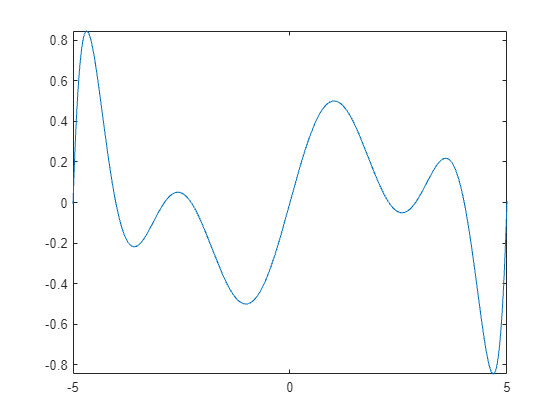

n1=10;
h1=10/n1;
x1=zeros(1,n1+1);
y1=zeros(1,n1+1);
x11=zeros(1,n1);
y11=zeros(1,n1);
for i=0 :n1
    x1(i+1)=-5+i*h1;
    y1(i+1)=x1(i+1)/(1+x1(i+1).^4);
end
lag1=Lag(x1,y1);
for i=0:n1-1
    x11(i+1)=-5+(i+1/2)*h1;
    y11(i+1) = subs(lag1,[sym("t")],[x11(i+1)]);
end
fplot(lag1);

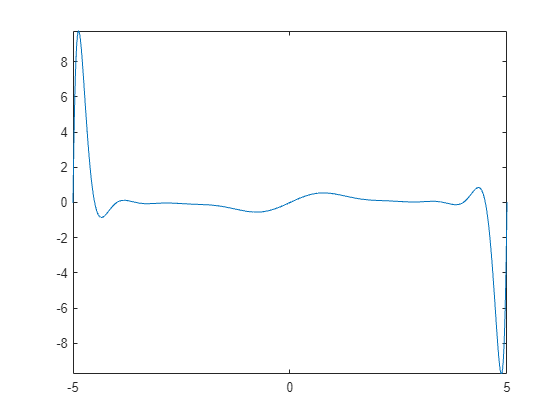

n2=20;
h2=10/n2;
x2=zeros(1,n2+1);
y2=zeros(1,n2+1);
x22=zeros(1,n2);
y22=zeros(1,n2);
for i=0 :n2
    x2(i+1)=-5+i*h2;
    y2(i+1)=x2(i+1)/(1+x2(i+1).^4);
end
lag2=Lag(x2,y2);
for i=0:n2-1
    x22(i+1)=-5+(i+1/2)*h2;
    y22(i+1) = subs(lag2,[sym("t")],[x22(i+1)]);
end
fplot(lag2);